clear; clc; close all;

#### Load and inspect the dataset

- Load and convert dataset into matrix

-  Initial categorical distribution 

- Statistical summary of data

- PCA calculation to understand attributes distribution for each instances

% 1. load data into matrices
filename = 'Meter_A_data.txt';
data_matrix  = readmatrix(filename);
% Display a message indicating that the data has been loaded successfully
fprintf('Data loaded successfully..\nNo of instances: %d | No of attributes: %d\n', size(data_matrix,1), size(data_matrix,2));

Data loaded successfully..
No of instances: 87 | No of attributes: 37



% 2. Initial class distribution
categorical_dist= categorical(data_matrix(:, end));
disp('Class distribution: Healthy vs Installation Effects');

Class distribution: Healthy vs Installation Effects


tabulate(categorical_dist);

  Value    Count   Percent
      1       35     40.23%
      2       52     59.77%



nCols = size(data_matrix,2);
nPred = nCols - 1;                 % last column is the label
X = data_matrix(:, 1:nPred);
Y = data_matrix(:, nPred+1);
Y = categorical(Y);


% 3. Get a basic statistical summary of the overall dataset
disp('3. Statistical summary of the predictor variables:');

3. Statistical summary of the predictor variables:


stats_min  = min(data_matrix(:,1:nPred))';
stats_max  = max(data_matrix(:,1:nPred))';
stats_mean = mean(data_matrix(:,1:nPred))';
stats_std  = std(data_matrix(:,1:nPred))';

varNames = sprintfc('Attr_%d', 1:nPred);
stats_table = table(stats_min, stats_max, stats_mean, stats_std, 'RowNames', varNames);
disp(stats_table);

               stats_min    stats_max    stats_mean    stats_std
               _________    _________    __________    _________

    Attr_1      0.79019      0.8471       0.82448       0.018146
    Attr_2      0.99706      1.0283        1.0127      0.0074176
    Attr_3      0.99324      1.0026       0.99746      0.0020457
    Attr_4       1.7813      8.4698        4.6824         1.8006
    Attr_5       2.2478      10.287        5.7545          2.224
    Attr_6       2.2345      10.128        5.6501         2.1884
    Attr_7       1.7856      8.5913        4.6897         1.8353
    Attr_8       1.7675      8.5817        4.7398         1.8347
    Attr_9       2.2613      10.299        5.7463          2


% 4. Visualize class separation using Principal Component Analysis (PCA)
[coeff, score, ~, ~, explained] = pca(data_matrix(:,1:nPred));

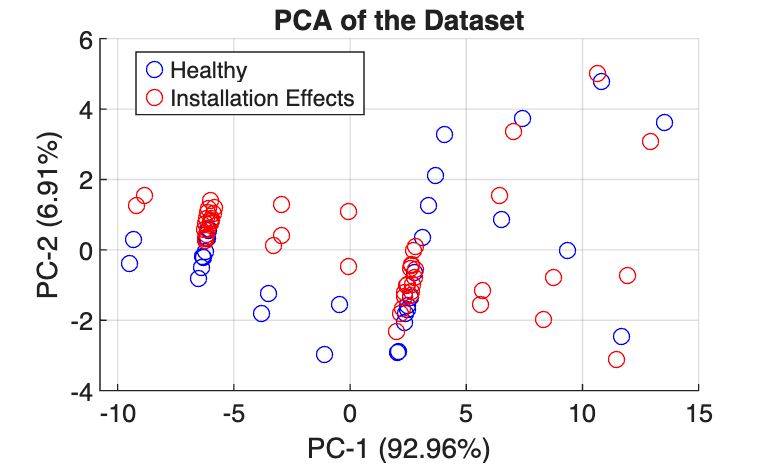

figure;
gscatter(score(:,1), score(:,2), categorical_dist, 'br', 'o');
xlabel(['PC-1 (' num2str(explained(1), '%.2f') '%)']);
ylabel(['PC-2 (' num2str(explained(2), '%.2f') '%)']);
title('PCA of the Dataset');
legend('Healthy', 'Installation Effects');
grid on;

#### Findings from Initial Observations

- Dataset has 87 instances, 37 attributes divided across 2 class ( Healthy , Installation effects)

PCA Plot analysis

- The **blue circles (Healthy)** and **red circles (Installation Effects)** form **partially distinct clusters** along the PC-1 axis.

- Healthy samples generally cluster around **two main regions** (around PC-1 ≈ −5 and PC-1 ≈ +5), while Installation Effects are more spread out but overlap in some areas.

- Since PC-1 explains 92.39% of variance, the **main distinguishing factor between Healthy and Installation Effects** lies along this axis.

- Some overlap between blue and red points indicates that **certain Installation Effect samples share similar characteristics** to Healthy ones — possibly mild or transitional cases.

#### Part 2 : Data Partition  + PLS Regression Model

- Separate data into Predictors (X ) and Response Variable (Y) 

- Splits data into train + test ( 70-30) 

- Build and Train the model with training data

- Make model prediction


% Separate the data into predictors (X) and the response variable (Y).
% The first 37 columns are the attributes (predictors) that are used to predict the final outcome.



% Split Data into Training and Test Sets 70-30
rng(42,'twister');
cv = cvpartition(Y,'HoldOut',0.30);

idxTrain = training(cv);
idxTest = test(cv);

% Create training and test sample sets using the indices.

XTrain = X(idxTrain,:);
YTrain = Y(idxTrain,:);
XTest = X(idxTest,:);
YTest = Y(idxTest,:);
fprintf('Training Samples: %d\n Test Samples: %d\n', size(XTrain,1), size(XTest,1));

Training Samples: 61
 Test Samples: 26



% Standardize the data (z-score)
disp('Standardizing data using z-score....');

Standardizing data using z-score....



% calculate mean and sdv from training set
[XTrain_Scaled, mu, sigma] = zscore(XTrain);
sigma(sigma==0) = 1;
XTest_scaled = (XTest - mu) ./ sigma;
disp('Standardization complete...')

Standardization complete...



% Model Building using MLE ( maximum likelihood estimate)

XTrain_b = [ones(size(XTrain_Scaled, 1),1), XTrain_Scaled];
features = size(XTrain_b,2);

% Convert YTrain to a numeric vector of 0s and 1s for the math.
% We'll map '1' (Healthy) to 0 and '2' (Installation Effects) to 1.
levels = categories(YTrain);
YTrain_numeric = (YTrain == levels{2}); % Will be 1 if class is '2', 0 otherwise.

lr = 0.01; % learning rate
itr = 1000; % iterations
beta = zeros(features, 1); % Initialize all beta coefficients to zero.

for i = 1:itr
    z = XTrain_b * beta;
    p = 1 ./ (1 + exp(-z));
    gradient = XTrain_b' * (YTrain_numeric - p);
    beta = beta + lr * gradient;
end

disp('Model training complete. Beta coefficients found:');

Model training complete. Beta coefficients found:


disp(beta');

    2.0573   -2.0836   -0.5696    1.9191   -0.6590   -0.8159   -0.6947   -0.4786   -0.4020   -0.6286   -0.9019   -0.7584   -0.8668   -0.2158    0.4735    1.3886   -0.7772   -0.2240    0.0751    0.6953    0.0655   -1.5058   -3.1086    1.9993   -0.4127   -2.4933    4.0645    1.1496   -0.4602    0.0004   -3.6821    0.2304    2.1119    4.8728   -2.0796    0.0194    3.3030



#### Part 3 : Model Predictions using Test Samples

- Test the model using test samples

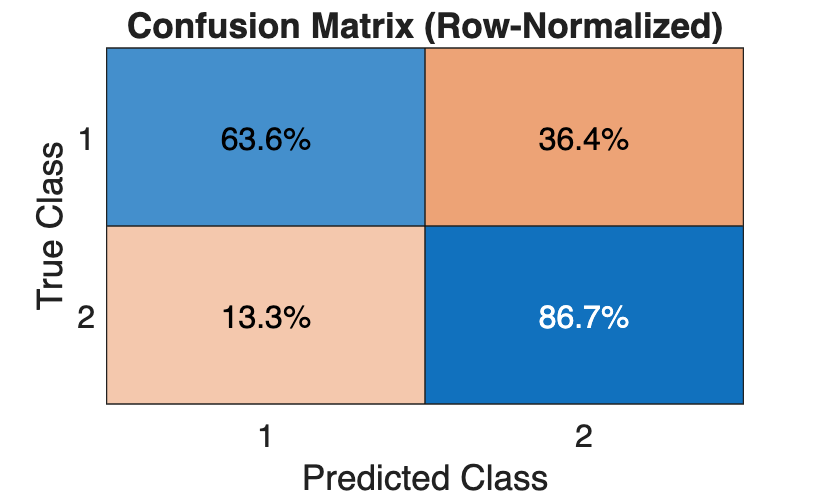

% use trained beta coeffs to predict outcomes
% Add an intercept term to the test data as well
XTest_b = [ones(size(XTest_scaled, 1), 1), XTest_scaled];

% Calculate the scores (probabilities) using the sigmoid function
z_test = XTest_b * beta;
scores = 1 ./ (1 + exp(-z_test));

% To get the final class predictions, we apply a threshold. If the
% probability is > 0.5, we classify it as '2', otherwise '1'.
YPred = scores > 0.5;
% Convert the logical 0s and 1s back to categorical labels '1' and '2'.
YPred = categorical(YPred, [0 1], levels);


% Evaluate Model through Plots

% 1. Confusion Matrix
figure;
cm = confusionchart(YTest, YPred, 'Normalization','row-normalized');
cm.Title = 'Confusion Matrix (Row-Normalized)';
cm.FontSize = 12;

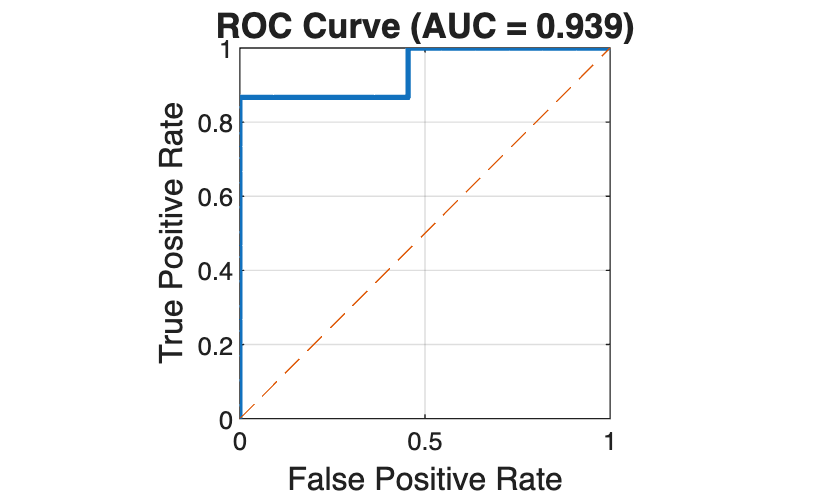


% --- PLOT 2: ROC Curve and AUC ---
[X_roc, Y_roc, ~, AUC] = perfcurve(YTest, scores, levels{2});
figure;
plot(X_roc, Y_roc, 'LineWidth', 2); hold on;
plot([0 1], [0 1], '--'); hold off;
xlim([0 1]); ylim([0 1]); axis square;
xlabel('False Positive Rate','FontSize',12);
ylabel('True Positive Rate','FontSize',12);
title(sprintf('ROC Curve (AUC = %.3f)', AUC),'FontSize',13);
grid on; box on;

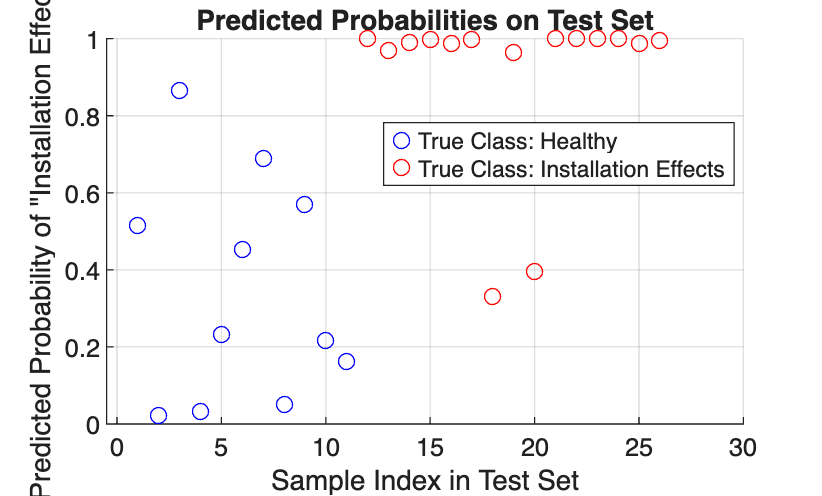


% --- PLOT 3: Scatter Plot of Predicted Probabilities ---
figure;
gscatter(1:length(YTest), scores, YTest, 'br', 'o');
xlabel('Sample Index in Test Set');
ylabel('Predicted Probability of "Installation Effects"');
title('Predicted Probabilities on Test Set');
legend('True Class: Healthy', 'True Class: Installation Effects', 'Location', 'best');
grid on;

#### Confusion Matrix Table

**Overall accuracy ≈ (63.6 % + 86.7 %)/2 ≈ 75 %**, depending on class balance.

The model is **better at detecting “Installation Effects”** than at recognizing healthy cases.

That pattern is typical when the fault class has clearer signal or the dataset is slightly imbalanced.